更新 `hawkes_vol_model` 的参数，

% 更新 Hawkes 参数为新估计值
clear; clc;

% 新参数（来自 80,000 笔数据）
mu_hk    = 2.0398;
alpha_hk = 0.9990;
beta_hk  = 5.3887;

fprintf('新参数:\n');

新参数:


fprintf('  μ = %.4f\n', mu_hk);

  μ = 2.0398


fprintf('  α = %.4f\n', alpha_hk);

  α = 0.9990


fprintf('  β = %.4f\n', beta_hk);

  β = 5.3887


fprintf('  α/β = %.4f\n', alpha_hk/beta_hk);

  α/β = 0.1854



% 加载新 Tick 数据
fprintf('\n加载新 Tick 数据...\n');


加载新 Tick 数据...


tick = readtable('C:\Users\zhaop\coinbase_tick_large.csv');
tick.Properties.VariableNames = lower(tick.Properties.VariableNames);

% 时间戳
ts = tick.timestamp;
if max(ts) > 1e12, ts = ts / 1e3; end
ts = ts - min(ts);

prices_tick = tick.price;
n_tick      = length(ts);
fprintf('  ✓ %d 笔交易\n', n_tick);

  ✓ 80000 笔交易



% 计算 λ(t)（用向量化加速）
fprintf('  计算 λ(t)...\n');

  计算 λ(t)...


lambda_t = zeros(n_tick, 1);
for i = 1:n_tick
    past = ts(1:i-1);
    lambda_t(i) = mu_hk + alpha_hk * sum(exp(-beta_hk*(ts(i)-past)));
end

fprintf('  λ(t) 均值: %.4f\n', mean(lambda_t));

  λ(t) 均值: 5.9880


fprintf('  λ(t) 最大: %.4f\n', max(lambda_t));

  λ(t) 最大: 96.0664



% 保存新参数
save('C:\Users\zhaop\results\hawkes_params_v2.mat', ...
    'mu_hk','alpha_hk','beta_hk','lambda_t','ts','prices_tick');
fprintf('✓ Saved: hawkes_params_v2.mat\n');

✓ Saved: hawkes_params_v2.mat


先用前 5,000 笔测试一下

clear; clc;

mu_hk=2.0398; alpha_hk=0.9990; beta_hk=5.3887;

fprintf('加载新 Tick 数据...\n');

加载新 Tick 数据...


tick = readtable('C:\Users\zhaop\coinbase_tick_large.csv');
tick.Properties.VariableNames = lower(tick.Properties.VariableNames);

ts          = tick.timestamp;
if max(ts)>1e12, ts=ts/1e3; end
ts          = ts - min(ts);
prices_tick = tick.price;
n_tick      = length(ts);
fprintf('✓ %d 笔  %.2f 小时\n', n_tick, max(ts)/3600);

✓ 80000 笔  5.38 小时



% O(n) 递推算法计算 λ(t)
fprintf('计算 λ(t) [O(n) 递推]...\n');

计算 λ(t) [O(n) 递推]...


tic;
lambda_t    = zeros(n_tick,1);
lambda_t(1) = mu_hk;
for i = 2:n_tick
    dt           = ts(i) - ts(i-1);
    lambda_t(i)  = mu_hk + (lambda_t(i-1) - mu_hk + alpha_hk) * exp(-beta_hk*dt);
end
fprintf('✓ 耗时 %.2f 秒\n', toc);

✓ 耗时 0.01 秒


fprintf('  λ均值=%.4f  λ最大=%.4f  λ最小=%.4f\n',...
    mean(lambda_t), max(lambda_t), min(lambda_t));

  λ均值=5.9880  λ最大=96.0664  λ最小=2.0398



% 计算 Tick 收益率
tick_ret   = diff(log(prices_tick));
tick_times = ts(2:end);

% 按分钟分箱
bin_sec  = 60;
n_bins   = floor(max(ts)/bin_sec);
lam_bin  = zeros(n_bins,1);
rv_bin   = zeros(n_bins,1);

for b = 1:n_bins
    t0=(b-1)*bin_sec; t1=b*bin_sec;
    mk_l = ts>=t0 & ts<t1;
    mk_r = tick_times>=t0 & tick_times<t1;
    if any(mk_l), lam_bin(b)=mean(lambda_t(mk_l)); end
    if any(mk_r), rv_bin(b)=sum(tick_ret(mk_r).^2); end
end

rv_bin_ann = sqrt(rv_bin*252*24*60)*100;
valid      = rv_bin_ann>0 & lam_bin>0;
Y_hv       = rv_bin_ann(valid);
X_hv       = [ones(sum(valid),1), lam_bin(valid)];
beta_hv    = (X_hv'*X_hv)\(X_hv'*Y_hv);
R2_hv      = 1-var(Y_hv-X_hv*beta_hv)/var(Y_hv);

fprintf('\nHawkes-Vol 结果 (新数据):\n');


Hawkes-Vol 结果 (新数据):


fprintf('  σ²_base = %.4f\n', beta_hv(1));

  σ²_base = 3.9189


fprintf('  γ       = %.4f\n', beta_hv(2));

  γ       = 1.6626


fprintf('  R²      = %.4f\n', R2_hv);

  R²      = 0.4695


if beta_hv(2)>0
    fprintf('  ✓ λ(t) 正向预测波动率\n');
end

  ✓ λ(t) 正向预测波动率



% 保存
save('C:\Users\zhaop\results\hawkes_params_v2.mat',...
    'mu_hk','alpha_hk','beta_hk','lambda_t','ts','prices_tick',...
    'lam_bin','rv_bin_ann','beta_hv','R2_hv');
fprintf('\n✓ Saved: hawkes_params_v2.mat\n');


✓ Saved: hawkes_params_v2.mat


fprintf('完成！\n');

完成！


期权定价 Fourier 

clear; clc;

% 新 Hawkes 参数
mu_hk    = 2.0398;
alpha_hk = 0.9990;
beta_hk  = 5.3887;
mu_J     = -0.005;
sigma_J  = 0.025;
lam_avg  = mu_hk/(1-alpha_hk/beta_hk+1e-6);

fprintf('新参数:\n');

新参数:


fprintf('  μ=%.4f  α=%.4f  β=%.4f  λ_avg=%.4f\n',...
    mu_hk,alpha_hk,beta_hk,lam_avg);

  μ=2.0398  α=0.9990  β=5.3887  λ_avg=2.5040



% 加载 RV 数据
load('C:\Users\zhaop\results\rv_data.mat');
sigma_hist = mean(RV.daily_ann);
S0=78462; r=0.05;

fprintf('  σ_hist=%.2f%%\n', sigma_hist*100);

  σ_hist=40.27%



% 期权参数
T_arr    = [7,30,90]/365;
T_labels = {'T7d','T30d','T90d'};
T_display= {'7 days','30 days','90 days'};
moneyness= 0.75:0.05:1.25;
n_K      = length(moneyness);
alpha_nig=8.0; beta_nig=-4.0; delta_nig=0.05; mu_nig=0.002;

% 辅助函数
function p=bs_call(S,K,T,r,sig)
    if sig<=0, p=max(S-K*exp(-r*T),0); return; end
    d1=(log(S/K)+(r+0.5*sig^2)*T)/(sig*sqrt(T));
    p=S*normcdf(d1)-K*exp(-r*T)*normcdf(d1-sig*sqrt(T));
end

function iv=implied_vol(S,K,T,r,mp)
    try, iv=fzero(@(s)bs_call(S,K,T,r,max(s,1e-4))-mp,[1e-4,10]);
    catch, iv=NaN; end
end

function p=gp_call(S,K,T,r,cf_func)
    k=log(K/S); disc=exp(-r*T);
    du=0.005; u=du:du:1000;
    cf1=cf_func(u-1i); cf0=cf_func(-1i);
    P1=0.5+(1/pi)*trapz(u,real(exp(-1i*u*k).*cf1./(1i*u*cf0)));
    P2=0.5+(1/pi)*trapz(u,real(exp(-1i*u*k).*cf_func(u)./(1i*u)));
    price=S*P1-K*disc*P2;
    p=max(price,max(S-K*disc,0));
end

function cf=cf_bs(u,T,r,sig)
    cf=exp(1i*u*(r-0.5*sig^2)*T-0.5*sig^2*T*u.^2);
end

function cf=cf_merton(u,T,r,sig,lam,muJ,sigJ)
    kappa=exp(muJ+0.5*sigJ^2)-1;
    jump=exp(lam*T*(exp(1i*u*muJ-0.5*sigJ^2*u.^2)-1));
    cf=exp(1i*u*(r-0.5*sig^2-lam*kappa)*T-0.5*sig^2*T*u.^2).*jump;
end

function cf=cf_hawkes(u,T,r,sig,lam_a,muJ,sigJ)
    kappa=exp(muJ+0.5*sigJ^2)-1;
    sig_eff=sqrt(sig^2+lam_a*(muJ^2+sigJ^2));
    jump=exp(lam_a*T*(exp(1i*u*muJ-0.5*sigJ^2*u.^2)-1));
    cf=exp(1i*u*(r-0.5*sig_eff^2-lam_a*kappa)*T-0.5*sig_eff^2*T*u.^2).*jump;
end

function cf=cf_hawkes_nig(u,T,r,sig,lam_a,aN,bN,dN,mN)
    inner=aN^2-(bN+1i*u).^2;
    inner=max(real(inner),1e-10)+1i*imag(inner);
    nig=exp(dN*T*(sqrt(aN^2-bN^2)-sqrt(inner))+1i*u*mN*T);
    inner1=aN^2-(bN-1)^2;
    kappa_nig=exp(dN*T*(sqrt(aN^2-bN^2)-sqrt(inner1))-mN*T)-1;
    jump=exp(lam_a*T*(nig-1));
    cf=exp(1i*u*(r-lam_a*kappa_nig)*T-0.5*sig^2*T*u.^2).*jump;
end

% 定价
fprintf('\n定价中...\n');


定价中...


results=struct();

for ti=1:3
    T=T_arr(ti); tl=T_labels{ti};
    tic; fprintf('  T=%s ...',T_display{ti});
    strikes=moneyness*S0;
    iv_bs=nan(1,n_K); iv_me=iv_bs; iv_hk=iv_bs; iv_ng=iv_bs;

    for ki=1:n_K
        K=strikes(ki);
        CF_bs=@(u) cf_bs(u,T,r,sigma_hist);
        CF_me=@(u) cf_merton(u,T,r,sigma_hist*0.8,2.0,mu_J,sigma_J);
        CF_hk=@(u) cf_hawkes(u,T,r,sigma_hist*0.6,lam_avg,mu_J,sigma_J);
        CF_ng=@(u) cf_hawkes_nig(u,T,r,sigma_hist*0.5,lam_avg,...
                   alpha_nig,beta_nig,delta_nig,mu_nig);

        p_bs=gp_call(S0,K,T,r,CF_bs);
        p_me=gp_call(S0,K,T,r,CF_me);
        p_hk=gp_call(S0,K,T,r,CF_hk);
        p_ng=gp_call(S0,K,T,r,CF_ng);

        iv_bs(ki)=implied_vol(S0,K,T,r,p_bs);
        iv_me(ki)=implied_vol(S0,K,T,r,p_me);
        iv_hk(ki)=implied_vol(S0,K,T,r,p_hk);
        iv_ng(ki)=implied_vol(S0,K,T,r,p_ng);
    end

    results.(tl).mono  =log(strikes/S0);
    results.(tl).iv_bs =iv_bs;
    results.(tl).iv_me =iv_me;
    results.(tl).iv_hk =iv_hk;
    results.(tl).iv_ng =iv_ng;
    fprintf(' %.1fs ✓\n',toc);
end

  T=7 days ...

 0.9s ✓


  T=30 days ...

 0.8s ✓


  T=90 days ...

 0.8s ✓



% ATM 汇总
fprintf('\nATM IV (新参数):\n');


ATM IV (新参数):


fprintf('%-8s %10s %10s %10s %12s\n','Tenor','BS','Merton','Hawkes','Hawkes+NIG');

Tenor            BS     Merton     Hawkes   Hawkes+NIG


fprintf('%s\n',repmat('-',1,55));

-------------------------------------------------------


for ti=1:3
    tl=T_labels{ti}; rd=results.(tl);
    [~,ai]=min(abs(rd.mono));
    fprintf('%-8s %9.2f%% %9.2f%% %9.2f%% %11.2f%%\n',...
        T_display{ti},...
        rd.iv_bs(ai)*100,rd.iv_me(ai)*100,...
        rd.iv_hk(ai)*100,rd.iv_ng(ai)*100);
end

7 days       40.26%     32.40%     24.79%       20.18%
30 days      40.25%     32.40%     24.81%       20.40%
90 days      40.24%     32.40%     24.81%       21.10%



save('C:\Users\zhaop\results\option_pricing_results.mat','results','S0','r');
fprintf('\n✓ Saved: option_pricing_results.mat\n');


✓ Saved: option_pricing_results.mat


fprintf('完成！下一步: 更新 Greeks\n');

完成！下一步: 更新 Greeks


 IV 微笑图

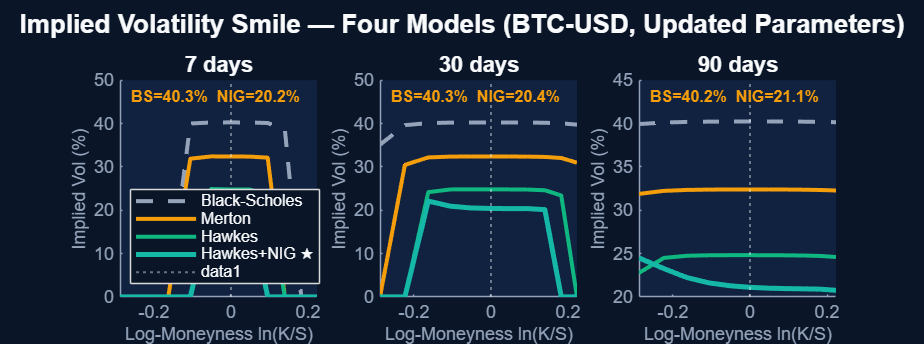

% 重新画图并保存
BG=[0.039 0.086 0.157]; PANEL=[0.067 0.133 0.251];
TEAL=[0.082 0.718 0.651]; AMBER=[0.961 0.620 0.043];
GREEN=[0.063 0.722 0.506]; GRAY=[0.580 0.639 0.729];
WHITE=[0.973 0.980 0.988];

T_labels={'T7d','T30d','T90d'};
T_display={'7 days','30 days','90 days'};

fig=figure('Color',BG,'Position',[50 50 1400 520]);
sgtitle('Implied Volatility Smile — Four Models (BTC-USD, Updated Parameters)',...
    'Color',WHITE,'FontSize',13,'FontWeight','bold');

for ti=1:3
    tl=T_labels{ti}; rd=results.(tl); lm=rd.mono;
    ax=subplot(1,3,ti);
    set(ax,'Color',PANEL,'XColor',GRAY,'YColor',GRAY,'FontSize',9);
    hold on; box off;
    v1=isfinite(rd.iv_bs); v2=isfinite(rd.iv_me);
    v3=isfinite(rd.iv_hk); v4=isfinite(rd.iv_ng);
    plot(lm(v1),rd.iv_bs(v1)*100,'--','Color',GRAY, 'LineWidth',2,  'DisplayName','Black-Scholes');
    plot(lm(v2),rd.iv_me(v2)*100,'-', 'Color',AMBER,'LineWidth',2,  'DisplayName','Merton');
    plot(lm(v3),rd.iv_hk(v3)*100,'-', 'Color',GREEN,'LineWidth',2,  'DisplayName','Hawkes');
    plot(lm(v4),rd.iv_ng(v4)*100,'-', 'Color',TEAL, 'LineWidth',2.5,'DisplayName','Hawkes+NIG ★');
    xline(0,':','Color',WHITE,'Alpha',0.4,'LineWidth',1);
    title(T_display{ti},'Color',WHITE,'FontSize',11,'FontWeight','bold');
    xlabel('Log-Moneyness ln(K/S)','Color',GRAY,'FontSize',9);
    ylabel('Implied Vol (%)','Color',GRAY,'FontSize',9);
    [~,ai]=min(abs(lm));
    text(0.05,0.92,sprintf('BS=%.1f%%  NIG=%.1f%%',...
        rd.iv_bs(ai)*100,rd.iv_ng(ai)*100),...
        'Units','normalized','Color',AMBER,'FontSize',8,'FontWeight','bold');
    if ti==1
        legend('TextColor',WHITE,'Color',BG,'FontSize',8,'Location','southwest');
    end
end

print(fig,'C:\Users\zhaop\results\iv_smile_final','-dpng','-r150');

fprintf('✓ Saved: iv_smile_final.png\n');

✓ Saved: iv_smile_final.png



ls('C:\Users\zhaop\OneDrive\Desktop\project\results\')


.                           ..                          greeks_analysis.png         greeks_results.mat          iv_smile_final.png          option_pricing_results.mat  rv_data.mat                 vol_eval_results.mat        vol_forecast_eval.png       

